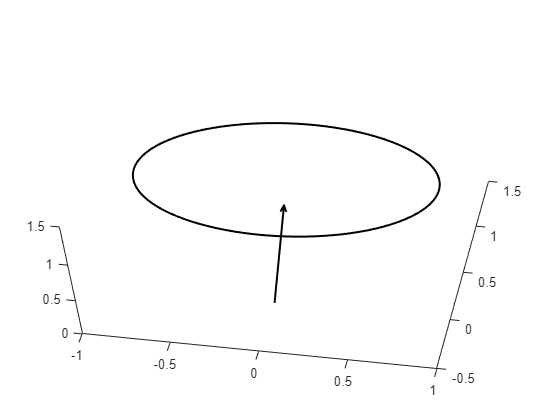

p1 = [0.5;1;1];

h1 = [0;1;3];
h1 = h1/norm(h1);

p2 = [0.5;1.2;0.8];

h2 = [0.6;0.5;0.5];

zv = [0;0;0];
C1 = gen_circle(h1,p1);
C2 = gen_circle(h2,p2);

[F1,V1] = gen_cone(h1,p1);
[F2,V2] = gen_cone(h2,p2);


figure
%view(3)
%view(45,45)
view(10,60)
hold on
camproj('perspective')

%arrow(zv,p1)
arrow(zv,h1)
%arrow(zv,p2)
%arrow(zv,h2)
plot3_mat(C1)

%plot3_mat(C2)
%patch('Faces', F1, 'Vertices', V1, 'FaceColor', 'w', 'EdgeColor', 'none', 'FaceLighting', 'gouraud')
%patch('Faces', F2, 'Vertices', V2, 'FaceColor', 'w', 'EdgeColor', 'none', 'FaceLighting', 'gouraud')
%lighting gouraud
%material shiny

line(zv, V_1)

Unrecognized function or variable 'V_1'.

line(zv, V_2)

hold off
axis equal padded
axis off
grid on
l = light('Position',[2 2 2],'Style','infinite');

center = h1*h1'*p1

Unrecognized function or variable 'h1'.

k1 = h1;
p_cam = campos'
%tip = zv;

% find equivalent camera position by scaling down (tip - camera) until
% camera is on plane of top of cone

cone_length = norm(k1'*center);
p_cam = p_cam * cone_length / norm(k1'*p_cam)

r = norm(center -  p1)



KxP1 = cross(k1,p1);
A_1 = [KxP1 -cross(k1,KxP1)]

p_cam_prog = (p_cam-center) - k1*k1'*(p_cam-center)
%A_1 * pinv(A_1)*p_cam
d = norm(p_cam_prog)
phi = acos(r/d)

theta_0 = subproblem1_linear(p1, p_cam, k1)

V_1 = rot(k1,theta_0 + phi)*p1
V_2 = rot(k1,theta_0 - phi)*p1



function arrow(t,h)

quiver3(t(1),t(2),t(3),h(1),h(2),h(3), 1, 'k', 'LineWidth',1.5)
end

function line(t,h)

plot3([t(1) h(1)],[t(2) h(2)],[t(3) h(3)], 'k', 'LineWidth',1.5)
end

function plot3_mat(mat)
plot3(mat(1,:),mat(2,:),mat(3,:), 'k', 'LineWidth',1.5)
end

function C = gen_circle(k,p)
    N = 100;
    C = NaN([3 N+1]);
    angles = linspace(0,2*pi,N+1);
    for i = 1:N
    C(:,i) = rot(k, angles(i))*p;
    end
    C(:,end)=C(:,1);
end

function [F,V] = gen_cone(k,p)
    zv = [0;0;0];
    V = gen_circle(k,p);
    N = length(V)-1;
    V = [zv V];

    F = [];
    for i = 2:N
        F = [F; i i+1  1];
    end
    F = [F; N+1 2 1];
    V = V';
end